% KaplanDeriaz3D - Hydro Turbine Blade Designer with CAD/Excel Export
% Copyright (C) 2026 Juan Fernandez Lozano
%
% This program is free software: you can redistribute it and/or modify
% it under the terms of the GNU General Public License as published by
% the Free Software Foundation, either version 3 of the License, or
% (at your option) any later version.
%
% This program is distributed in the hope that it will be useful,
% but WITHOUT ANY WARRANTY; without even the implied warranty of
% MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE. See the
% GNU General Public License for more details.
%
% You should have received a copy of the GNU General Public License
% along with this program. If not, see <https://www.gnu.org/licenses/>.

% =========================================================================
% SCRIPT DE MATLAB: DISEÑO 3D DE ÁLABE TURBINA DERIAZ DIAGONAL Y RODETE (TFM)
% ROTACIÓN DEL RODETE: ANTIHORARIA (Visto desde arriba)
%
% Este código resuelve numéricamente la ecuación diferencial del alabeado
% para un canal cónico-esférico considerando eficiencias hidrodinámicas,
% la hipótesis de Euler (H_inf), la integración curvilínea 3D de la cuerda,
% el cálculo analítico del número de álabes (Z) y el renderizado completo.
% =========================================================================
clear; clc; close all;

%% ========================================================================
% BLOQUE 1: PARÁMETROS ENERGÉTICOS, GEOMÉTRICOS Y EFICIENCIAS
% =========================================================================
RPM = 150;                % Velocidad de rotación del rodete (rpm)
Q0 = 110;                  % Caudal volumétrico nominal extraído del salto (m^3/s)
Hn = 60;                  % Altura neta disponible (m) 
g = 9.81;                 % Aceleración de la gravedad (m/s^2)

% Rendimientos de la turbomáquina (Eficiencias internas)
eta_h = 0.91;             % Eficiencia hidráulica
eta_v = 0.97;             % Eficiencia volumétrica
eta_o = 0.98;             % Eficiencia orgánica/mecánica
eta_t = eta_h * eta_v * eta_o; % Rendimiento total de la turbina

% Radios esféricos de contorno (Cubo y Carcasa):
Re_int = 2;             % Radio esférico del cubo (m)
Re_ext = 2.6;             % Radio esférico de la carcasa (m)

% Límites del paso meridiano (ángulos cónicos):
gamma1_deg = 30;          % Entrada al rodete (grados)
gamma2_deg = 60;          % Salida del rodete (grados)

%% ========================================================================
% BLOQUE 2: CINEMÁTICA Y CONVERSIONES
% =========================================================================
omega = (2 * pi * RPM) / 60;              % Velocidad angular (rad/s)
Q_real = Q0 * eta_v;                      % Caudal útil efectivo (m^3/s)
gamma1 = deg2rad(gamma1_deg);             % Inclinación de entrada (rad)
gamma2 = deg2rad(gamma2_deg);             % Inclinación de salida (rad)

% Potencias teóricas y útiles del salto
W_n = 1000 * g * Q0 * Hn;                 % Potencia hidráulica bruta disponible (W)
W_t = W_n * eta_t;                        % Potencia mecánica útil entregada al eje (W)
H_inf = Hn * eta_h;                       % Energía teórica según hipótesis de Euler (m)

% Radio esférico medio equivalente (Media Logarítmica Exacta):
Re_medio = (Re_ext - Re_int) / log(Re_ext / Re_int);

%% ========================================================================
% BLOQUE 3: DISCRETIZACIÓN ESPACIAL Y MATRICES DE DATOS
% =========================================================================
N_radios = 30;  % Número de líneas de corriente entre cubo y carcasa
N_cuerda = 50;  % Número de pasos en la dirección del flujo (gamma)

Re_vec = linspace(Re_int, Re_ext, N_radios);
gamma_vec = linspace(gamma1, gamma2, N_cuerda);

X = zeros(N_cuerda, N_radios);
Y = zeros(N_cuerda, N_radios);
Z = zeros(N_cuerda, N_radios);
RC = zeros(N_cuerda, N_radios);

%% ========================================================================
% BLOQUE 4: INTEGRACIÓN NUMÉRICA 3D (CANAL CÓNICO-ESFÉRICO)
% =========================================================================
for i = 1:N_radios
    Re = Re_vec(i);         % Radio esférico de la línea de corriente actual
    
    % --- 1. TRIÁNGULO DE VELOCIDADES A LA ENTRADA (gamma1) ---
    rc1 = Re * cos(gamma1);                     % Radio cilíndrico de entrada
    U1 = omega * rc1;                           % Velocidad de arrastre entrada
    Vm1 = Q_real / (2 * pi * Re * cos(gamma1) * (Re_ext - Re_int)); % Vm meridiana
    
    % Componente acimutal requerida por Euler (V_theta1 * U1 = g * H_inf)
    Vtheta1 = (g * H_inf) / U1;
    
    % Control de seguridad física:
    if Vtheta1 >= U1
        error('Error físico en Re = %.3f m: V_theta1 (%.2f m/s) >= U1 (%.2f m/s).', Re, Vtheta1, U1);
    end
    
    beta1 = atan2(Vm1, (U1 - Vtheta1));         % Ángulo cinemático de entrada
    
    % --- 2. TRIÁNGULO DE VELOCIDADES A LA SALIDA (gamma2) ---
    rc2 = Re * cos(gamma2);                     % Radio cilíndrico de salida
    U2 = omega * rc2;                           % Velocidad de arrastre salida
    Vm2 = Q_real / (2 * pi * Re * cos(gamma2) * (Re_ext - Re_int)); % Vm acelerada
    
    beta2 = atan2(Vm2, U2);                     % Ángulo cinemático de salida (Vtheta2 = 0)
    
    % --- 3. LEY DE INTERPOLACIÓN CÚBICA DEL ÁNGULO BETA(gamma) ---
    t = (gamma_vec - gamma1) / (gamma2 - gamma1);
    polinomio_cubico = 3*(t.^2) - 2*(t.^3);
    beta_gamma = beta1 + (beta2 - beta1) .* polinomio_cubico;
    
    % --- 4. INTEGRACIÓN NUMÉRICA DE LA ECUACIÓN DIFERENCIAL ---
    theta_rel = 0;
    
    for j = 1:N_cuerda
        gamma_actual = gamma_vec(j);
        
        if j > 1
            d_gamma = gamma_vec(j) - gamma_vec(j-1);
            
            % Evaluación en el punto medio del paso
            gamma_mid = (gamma_vec(j) + gamma_vec(j-1)) / 2;
            beta_mid  = (beta_gamma(j) + beta_gamma(j-1)) / 2;
            
            % Ecuación diferencial exacta del álabe diagonal Deriaz:
            d_theta_rel = (cot(beta_mid) / cos(gamma_mid)) * d_gamma;
            
            % Giro antihorario (retraso del fluido)
            theta_rel = theta_rel - d_theta_rel;
        end
        
        % Coordenadas cilíndricas locales:
        rc_local = Re * cos(gamma_actual);
        z_local  = -Re * sin(gamma_actual);
        
        % Conversión a coordenadas cartesianas 3D:
        X(j, i) = rc_local * cos(theta_rel);
        Y(j, i) = rc_local * sin(theta_rel);
        Z(j, i) = z_local;
        RC(j, i) = rc_local;
    end
end

%% ========================================================================
% BLOQUE 5: CÁLCULO RIGUROSO DEL NÚMERO ÓPTIMO DE ÁLABES (Z)
% Integration de la cuerda 3D sobre Re_medio y criterio de solidez
% =========================================================================
% 1. Localización de la línea de corriente más cercana a Re_medio
[~, idx_Rmedio] = min(abs(Re_vec - Re_medio));

% 2. Integración curvilínea exacta de la cuerda 3D sobre Re_medio
dx = diff(X(:, idx_Rmedio)); % diff resta cada elemento de su siguiente(Δx1,Δx2)
dy = diff(Y(:, idx_Rmedio)); 
dz = diff(Z(:, idx_Rmedio));
dL = sqrt(dx.^2 + dy.^2 + dz.^2);
L_cuerda_real = sum(dL); % Cuerda 3D real integrada (m)

% 3. Radio cilíndrico medio equivalente para el desarrollo del paso
rc_promedio_medio = mean(RC(:, idx_Rmedio));

% 4. Solidez hidrodinámica objetivo (sigma = L_cuerda / paso_tangencial)
sigma_target = 1.4; % Valor coherente para turbinas Deriaz

% 5. Determinación del número de álabes Z
paso_tangencial_req = L_cuerda_real / sigma_target;
Z_calculado = (2 * pi * rc_promedio_medio) / paso_tangencial_req;
Z_optimo = round(Z_calculado);

% Límites físicos de seguridad para turbinas Deriaz
Z_optimo = max(4, min(Z_optimo, 12));

% Velocidad específica cinemática (nq) para informe técnico
nq = RPM * sqrt(Q0) / ((g*Hn)^(3/4));

fprintf('=======================================================\n');

fprintf('   RESULTADOS DIMENSIONAMIENTO TURBINA DERIAZ (TFM)    \n');

   RESULTADOS DIMENSIONAMIENTO TURBINA DERIAZ (TFM)    


fprintf('=======================================================\n');

fprintf('Velocidad angular específica  (nq) : %.2f rpm\n', nq);

Velocidad angular específica  (nq) : 13.17 rpm


fprintf('Caudal útil efectivo (Q_real)        : %.2f m^3/s\n', Q_real);

Caudal útil efectivo (Q_real)        : 106.70 m^3/s


fprintf('Potencia útil en el eje (Wt)         : %.2f kW\n', W_t / 1000);

Potencia útil en el eje (Wt)         : 56008.27 kW


fprintf('Cuerda 3D integrada (L_cuerda)       : %.3f m\n', L_cuerda_real);

Cuerda 3D integrada (L_cuerda)       : 1.574 m


fprintf('Número de álabes óptimo (Z)          : %d álabes\n', Z_optimo);

Número de álabes óptimo (Z)          : 9 álabes


fprintf('=======================================================\n\n');

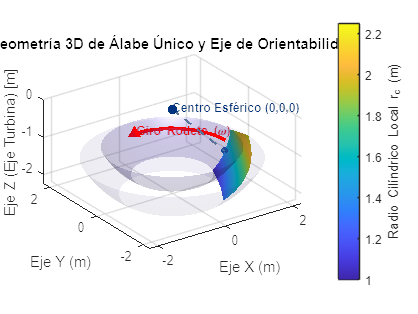

%% ========================================================================
% BLOQUE 6: RENDERIZADO VISUAL EN 3D - FIGURA 1 (ÁLABE ÚNICO DERIAZ)
% =========================================================================
figure('Name', 'Figura 1: Álabe Único de Referencia - Turbina Deriaz', 'Color', 'w');

surf(X, Y, Z, RC, 'FaceColor', 'interp', 'EdgeColor', [0.1 0.1 0.1], 'EdgeAlpha', 0.25);
hold on;

% Malla de contorno esférico (Cubo y Carcasa)
[theta_grid, gamma_grid] = meshgrid(linspace(0, 2*pi, 60), linspace(gamma1, gamma2, 30));

% Contorno interior (Cubo):
X_cubo = Re_int * cos(gamma_grid) .* cos(theta_grid);
Y_cubo = Re_int * cos(gamma_grid) .* sin(theta_grid);
Z_cubo = -Re_int * sin(gamma_grid);
mesh(X_cubo, Y_cubo, Z_cubo, 'FaceColor', [0.5 0.5 0.5], 'FaceAlpha', 0.20, 'EdgeColor', [0.4 0.4 0.4]);

% Contorno exterior (Carcasa - Tono Azul Cristalino Neutro):
X_carcasa = Re_ext * cos(gamma_grid) .* cos(theta_grid);
Y_carcasa = Re_ext * cos(gamma_grid) .* sin(theta_grid);
Z_carcasa = -Re_ext * sin(gamma_grid);
mesh(X_carcasa, Y_carcasa, Z_carcasa, ...
    'FaceColor', [0.2 0.5 0.8], ...
    'FaceAlpha', 0.08, ...
    'EdgeColor', [0.3 0.7 0.9], ...
    'EdgeAlpha', 0.20);

% --- CENTRO ESFÉRICO Y EJE SUTIL EN LA RAÍZ ---
% 1. Centro Esférico (0,0,0) en Azul Oscuro
plot3(0, 0, 0, 'o', 'MarkerSize', 7, 'MarkerFaceColor', [0.0 0.2 0.5], 'MarkerEdgeColor', 'none'); 

% 2. Punto de encaste en la raíz del cubo (i=1 -> cubo, j_mid -> centro de cuerda)
j_mid = round(N_cuerda / 2);
x_raiz = X(j_mid, 1);
y_raiz = Y(j_mid, 1);
z_raiz = Z(j_mid, 1);

% 3. Eje discontinuo gris-azulado sutil (para exactamente en la raíz)
color_eje_sutil = [0.35 0.45 0.60 0.45]; % RGBA: Gris-azul semi-transparente
plot3([0, x_raiz], [0, y_raiz], [0, z_raiz], '--', 'Color', color_eje_sutil, 'LineWidth', 1.5);

% 4. Punto sutil en la unión con el cubo
plot3(x_raiz, y_raiz, z_raiz, 'o', 'MarkerSize', 5, 'MarkerFaceColor', [0.1 0.3 0.6], 'MarkerEdgeColor', 'none'); 

text(0.02, 0.02, 0.05, 'Centro Esférico (0,0,0)', 'Color', [0.0 0.2 0.5], 'FontSize', 9, 'FontWeight', 'bold');

% Indicador del sentido de rotación (Antihorario)
ang_flecha = linspace(0, pi/2, 20);
r_flecha = Re_ext * cos(gamma1) * 0.7;
z_flecha = -Re_ext * sin(gamma1) + 0.05;

plot3(r_flecha*cos(ang_flecha), r_flecha*sin(ang_flecha), z_flecha*ones(size(ang_flecha)), 'r-', 'LineWidth', 2.5);
plot3(0, r_flecha, z_flecha, 'r^', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
text(0.05, r_flecha + 0.05, z_flecha + 0.03, 'Giro Rodete (\omega)', 'Color', 'r', 'FontSize', 9, 'FontWeight', 'bold');

title('Geometría 3D de Álabe Único y Eje de Orientabilidad');
xlabel('Eje X (m)'); ylabel('Eje Y (m)'); zlabel('Eje Z (Eje Turbina) [m]');
colormap(parula(256));
clim([min(RC(:)), max(RC(:))]);
h_bar = colorbar; ylabel(h_bar, 'Radio Cilíndrico Local r_c (m)', 'FontSize', 10);
axis equal; grid on; view(-35, 25);
camlight('headlight'); lighting gouraud; shading interp;

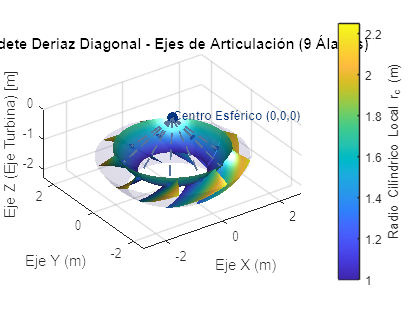


%% ========================================================================
% BLOQUE 7: RENDERIZADO VISUAL EN 3D - FIGURA 2 (RODETE DERIAZ COMPLETO)
% =========================================================================
figure('Name', sprintf('Figura 2: Rodete Deriaz Completo Optimizado (%d Álabes)', Z_optimo), 'Color', 'w');
hold on;

delta_angle = (2 * pi) / Z_optimo;

% 1. Centro Esférico (0,0,0) en Azul Oscuro
plot3(0, 0, 0, 'o', 'MarkerSize', 8, 'MarkerFaceColor', [0.0 0.2 0.5], 'MarkerEdgeColor', 'none');
text(0.03, 0.03, 0.06, 'Centro Esférico (0,0,0)', 'Color', [0.0 0.2 0.5], 'FontSize', 9, 'FontWeight', 'bold');

% 2. Bucle de clonación angular de álabes y ejes de articulación sutiles
for k = 1:Z_optimo
    current_angle = (k - 1) * delta_angle;
    
    % Rotación de la superficie del álabe
    X_rot = X * cos(current_angle) - Y * sin(current_angle);
    Y_rot = X * sin(current_angle) + Y * cos(current_angle);
    Z_rot = Z;
    
    surf(X_rot, Y_rot, Z_rot, RC, 'FaceColor', 'interp', 'EdgeColor', 'none');
    
    % Coordenada de la raíz (articulación) para el álabe k
    x_raiz_k = X_rot(j_mid, 1);
    y_raiz_k = Y_rot(j_mid, 1);
    z_raiz_k = Z_rot(j_mid, 1);
    
    % Dibujar eje discontinuo gris-azulado desde (0,0,0) HASTA la raíz (sin sobresalir)
    plot3([0, x_raiz_k], [0, y_raiz_k], [0, z_raiz_k], '--', 'Color', color_eje_sutil, 'LineWidth', 1.3);
    
    % Punto sutil de encaste en la superficie del cubo
    plot3(x_raiz_k, y_raiz_k, z_raiz_k, 'o', 'MarkerSize', 4.5, 'MarkerFaceColor', [0.1 0.3 0.6], 'MarkerEdgeColor', 'none'); 
end

% --- RENDERIZADO SÓLIDO DEL CUBO CÓNICO-ESFÉRICO ---
surf(X_cubo, Y_cubo, Z_cubo, Re_int * cos(gamma_grid), 'FaceColor', [0.4 0.4 0.4], 'EdgeColor', 'none', 'FaceAlpha', 0.95);

% Contorno exterior transparente de carcasa (Azul Cristalino Neutro)
mesh(X_carcasa, Y_carcasa, Z_carcasa, ...
    'FaceColor', [0.2 0.5 0.8], ...
    'FaceAlpha', 0.15, ...
    'EdgeColor', [0.4 0.7 0.9], ...
    'EdgeAlpha', 0.15);

title(sprintf('Rodete Deriaz Diagonal - Ejes de Articulación (%d Álabes)', Z_optimo));
xlabel('Eje X (m)'); ylabel('Eje Y (m)'); zlabel('Eje Z (Eje Turbina) [m]');
colormap(parula(256));
clim([min(RC(:)), max(RC(:))]);
h_bar2 = colorbar; ylabel(h_bar2, 'Radio Cilíndrico Local r_c (m)', 'FontSize', 10);
axis equal; grid on; view(-35, 30);
camlight('headlight'); lighting gouraud; shading interp;